# Assignment 11

William Watkins, in collaboration with Addi Woodard and Sarah Foley

Clear the workspace

clear all
close all
clc

Get our constants, A matrix, etc.

global Constants E1 Alat IPrime DOrig calli latNDContDer
B747LatValues();

## 1.

Using the Roll Mode Approximation from eqn (6.8, 8) we get 

rollEigApp = calli.Lp

rollEigApp = -0.5672

DOrig(3)

ans = -0.7648

The original eigenvalue was $\lambda_R = -0.7648$, while the approximated eigenvalue is $\lambda_{R,App} = -0.5672$.  This is very inaccurate; the approximated eigenvalue is $35 \%$ smaller than the true eigenvalue.

Use the Spiral Mode approximation from eqn (6.8, 3) and (6.8, 4),

E = Constants.g * ( (calli.Lv * calli.Nr - calli.Lr * calli.Nv) * cos(E1.theta0) ...
    + (calli.Lp * calli.Nv - calli.Lv * calli.Np) * sin(E1.theta0) );
D = -Constants.g * (calli.Lv * cos(E1.theta0) + calli.Nv * sin(E1.theta0) )...
    + E1.u0 * (calli.Lv * calli.Np - calli.Lp * calli.Nv);
spiralEigApp = -E/D

spiralEigApp = -0.0052

DOrig(4)

ans = -0.0051

We can see that the Spiral Mode approximation given in the book is a very accurate approximation, with the original $\lambda_S = -0.0051$, while the approximated eigenvalue $\lambda_{S,App} = -0.0052$.  This is a difference of less than $2 \%$!

Thankfully, thanks to McRuer et al. (1973), we are given a much more accurate system to approximate both the roll and spiral eigenvalues for the B747.  Forming the A matrix from (6.8, 10), we obtain the following

ASRApp(1, 1) = 0;
ASRApp(1, 2) = 0;
ASRApp(1, 3) = -E1.u0;
ASRApp(1, 4) = Constants.g;

ASRApp(2, 1) = calli.Lv;
ASRApp(2, 2) = calli.Lp;
ASRApp(2, 3) = calli.Lr;
ASRApp(2, 4) = 0;

ASRApp(3, 1) = calli.Nv;
ASRApp(3, 2) = calli.Np;
ASRApp(3, 3) = calli.Nr;
ASRApp(3, 4) = 0;

ASRApp(4, 1) = 0;
ASRApp(4, 2) = 1;
ASRApp(4, 3) = 0;
ASRApp(4, 4) = 0;

[~, DSRApp] = eig(ASRApp);
DSRApp = diag(DSRApp);
DSRApp = DSRApp(3:4)

DSRApp =    -0.7576
   -0.0052


The new approximated eigenvalues are $\lambda_{S,App} = -0.0052$ and $\lambda_{R,App} = -0.7576$.  Using the approximation from McRuer et al., the error for each eigenvalue is now $\approx 0\%$ and $\approx 1 \%$, respectively.  These values are much better!  

## 2. 

### a) 

The non-dimensional control derivatives are given in the B747LatValues function.  From Table 7.1, page 207, 

latDimContDer.da.Y = 0.5 * latNDContDer.da.Cy * E1.rho * E1.S * E1.u0^2;
latDimContDer.da.L = 0.5 * latNDContDer.da.Cl * E1.rho * E1.S * E1.b * E1.u0^2;
latDimContDer.da.N = 0.5 * latNDContDer.da.Cn * E1.rho * E1.S * E1.b * E1.u0^2;

latDimContDer.dr.Y = 0.5 * latNDContDer.dr.Cy * E1.rho * E1.S * E1.u0^2;
latDimContDer.dr.L = 0.5 * latNDContDer.dr.Cl * E1.rho * E1.S * E1.b * E1.u0^2;
latDimContDer.dr.N = 0.5 * latNDContDer.dr.Cn * E1.rho * E1.S * E1.b * E1.u0^2;

The B matrix for the lateral case is then

Blat(1, 1) = latDimContDer.da.Y / E1.m;
Blat(1, 2) = latDimContDer.dr.Y / E1.m;

Blat(2, 1) = (latDimContDer.da.L / IPrime.x) + IPrime.zx * latDimContDer.da.N;
Blat(2, 2) = (latDimContDer.dr.L / IPrime.x) + IPrime.zx * latDimContDer.dr.N;

Blat(3, 1) = IPrime.zx * latDimContDer.da.L + (latDimContDer.da.N / IPrime.z);
Blat(3, 2) = IPrime.zx * latDimContDer.dr.L + (latDimContDer.dr.N / IPrime.z);

Blat(4, 1) = 0;
Blat(4, 2) = 0;

### b) 

Constructing the augmented A matrix, we will just add onto the A matrix constructed in B747LatValues.

Alat(1:4, 5:6) = 0;

Alat(5, 1) = 0;
Alat(5, 2) = 0;
Alat(5, 3) = sec(E1.theta0);
Alat(5, 4) = 0;
Alat(5, 5) = 0;
Alat(5, 6) = 0;

Alat(6, 1) = 1;
Alat(6, 2) = 0;
Alat(6, 3) = 0;
Alat(6, 4) = 0;
Alat(6, 5) = E1.u0 * cos(E1.theta0);
Alat(6, 6) = 0;

For the augmented B matrix, we will just add onto the B matrix from above.

Blat(5:6, 1:2) = 0;

## 3. 

Using each of the following changes to $\delta a$, $\delta r$, and K, we plot the locus of eigenvalues.

### a) $\Delta \delta_a = K \Delta \phi$, $\Delta \delta_r = 0$, $\left| K \right| = 0 \colon 0.01 \colon 10$ (pos. feedback only)

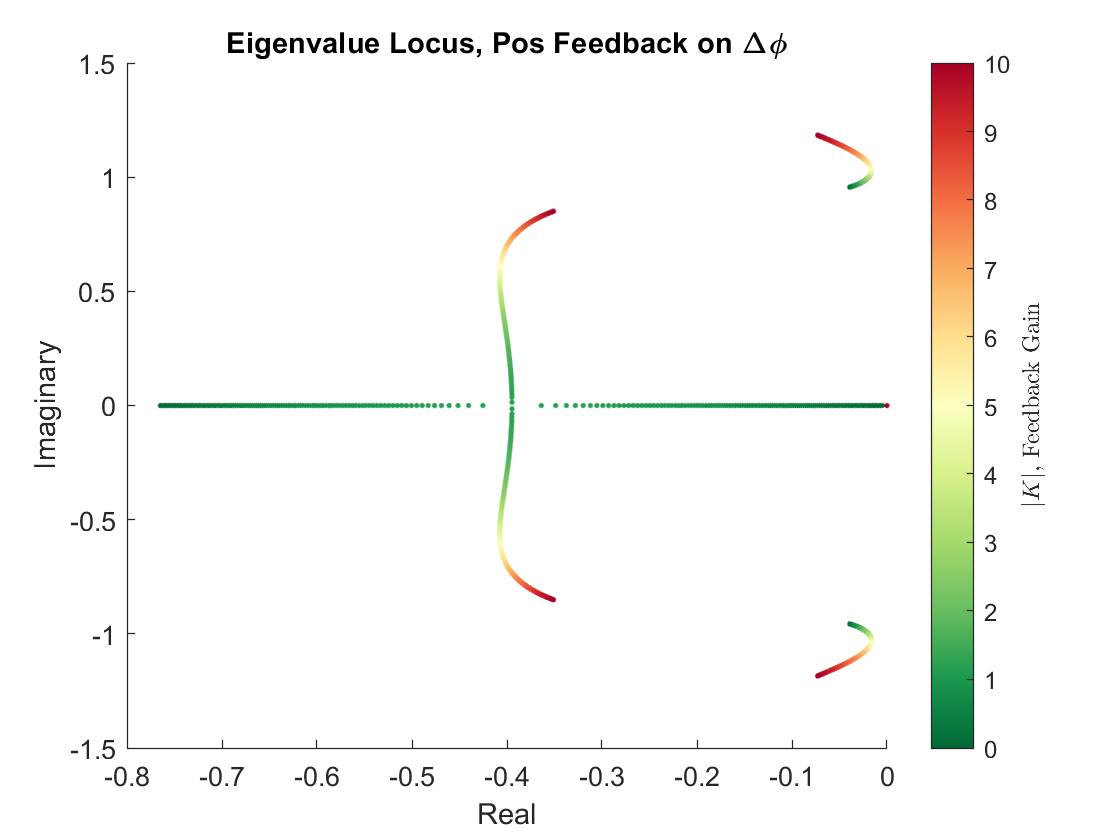

K = 0:0.01:10;
DCLF = zeros([length(K) 6]);
mycolormap = customcolormap(linspace(0,1,11), {'#a60126','#d7302a','#f36e43','#faac5d','#fedf8d','#fcffbf','#d7f08b','#a5d96b','#68bd60','#1a984e','#006936'}, length(K));
figure()
hold on
for i = 1:length(K)
    Klat(1, 1:6) = [0, 0, 0, K(i), 0, 0];
    Klat(2, 1:6) = [0, 0, 0, 0,    0, 0];
    ALatAugCL = Alat + Blat * Klat;
    [VCL, DCL] = eig(ALatAugCL);
    DCL = diag(DCL);
    plot(real(DCL), imag(DCL), 'Color', mycolormap(i,:), 'Marker', '.', 'LineStyle', 'none');
end
colormap(mycolormap);
gaincol = colorbar();
caxis([0 10]);
gaincol.Label.String = '$\left| K \right|$, Feedback Gain';
gaincol.Label.Interpreter = 'latex';
title('Eigenvalue Locus, Pos Feedback on \Delta\phi');
xlabel('Real');
ylabel('Imaginary');
hold off

K = 0;
Klat = 0;
ALatAugCL = 0;
VCL = 0;
DCL = 0;

From Chapters 2 and 3 in the book, it's observed that airplanes have inherent aerodynamic rotational stiffness in pitch and yaw, but no such stiffness exists for rotations about the velocity vector (roll).  By having $\phi$ feed into the aileron control, we are adding a new aerodynamic rotational stiffness, and as such we expect a large impact on the airplane's lateral dynamics.  We can see from the graph above that this is indeed the case!  As we increase the value of K, the time constants of the two nonperiodic modes are seen to change very rapidly.  Specifically, the time constant for the Roll mode decreases (real part gets smaller), while the time constant for the Spiral mode increases.  This continues until $K=1.21$, that is, $1.21 ^{\circ}$ of aileron for $1 ^{\circ}$ of bank, at which point these modes have disappeared and are replaced by a single low frequency, heavily damped oscillation.  The Dutch Roll is largely unaffected by the aileron feedback.

On the graph, the two nonperiodic modes are seen on the '0' line, and they progress to the center of the graph until they join to form the low frequency, heavily damped oscillation that extends above and below the '0' line.  The Dutch Roll mode is found in the upper right- and lower right-hand corners of the graph.

### b) $\Delta \delta_a = K \Delta p$, $\Delta \delta_r = 0$, $\left| K \right| = 0 \colon 0.01 \colon 10$ (neg. feedback only)

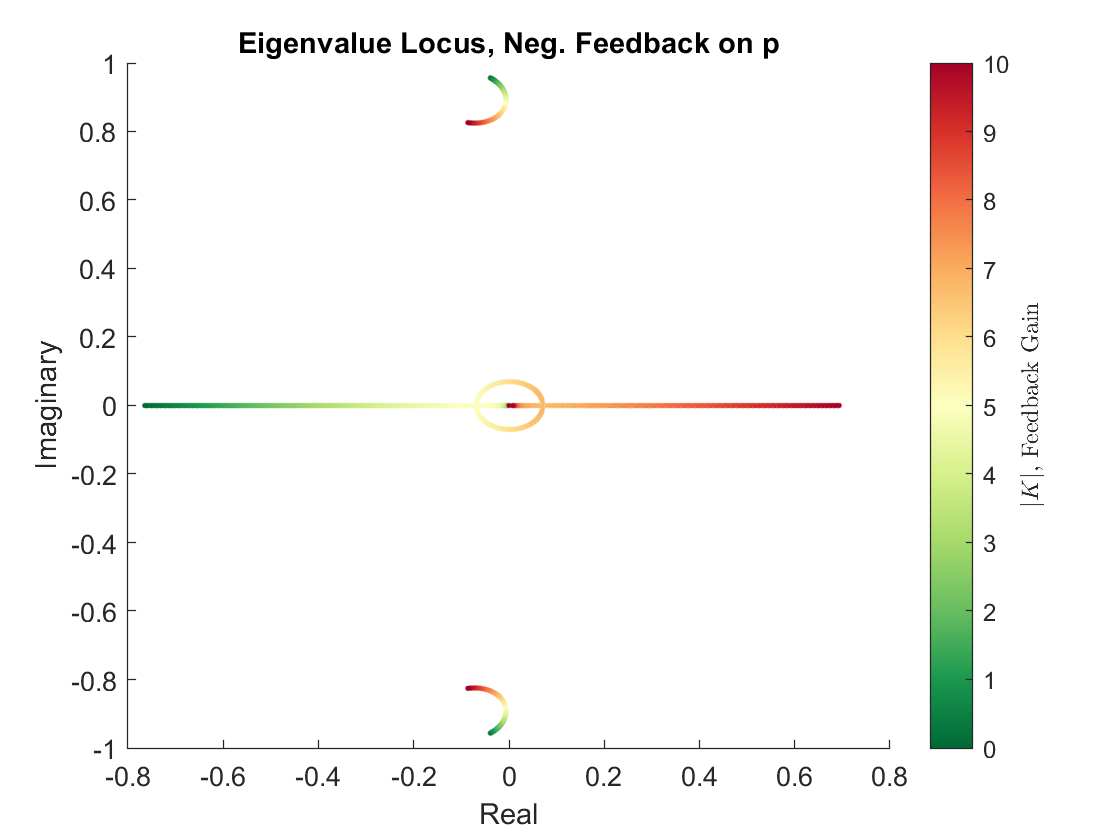

K = 0:0.01:10;
mycolormap = customcolormap(linspace(0,1,11), {'#a60126','#d7302a','#f36e43','#faac5d','#fedf8d','#fcffbf','#d7f08b','#a5d96b','#68bd60','#1a984e','#006936'}, length(K));
figure()
hold on
for i = 1:length(K)
    Klat(1, 1:6) = [0, K(i), 0, 0, 0, 0];
    Klat(2, 1:6) = [0, 0,    0, 0, 0, 0];
    ALatAugCL = Alat - Blat * Klat;
    [VCL, DCL] = eig(ALatAugCL);
    DCL = diag(DCL);
    plot(real(DCL), imag(DCL), 'Color', mycolormap(i,:), 'Marker', '.', 'LineStyle', 'none');
end
colormap(mycolormap);
gaincol = colorbar();
caxis([0 10]);
gaincol.Label.String = '$\left| K \right|$, Feedback Gain';
gaincol.Label.Interpreter = 'latex';
title('Eigenvalue Locus, Neg. Feedback on p');
xlabel('Real');
ylabel('Imaginary');
hold off

K = 0;
Klat = 0;
ALatAugCL = 0;
VCL = 0;
DCL = 0;

The largest effect of the aileron feedback in this case is seen on the Roll mode.  The Dutch Roll mode has increased damping up until $\left| K \right| \approx 5$, and then the damping ratio decreases as the real part gets larger in magnitude.  The Roll mode time constant is decreased, and the magnitude of the Spiral mode time constant is also decreased after initially increasing.  For a brief period, $\approx 5 < \left| K \right| < \approx 7$, the two nonperiodic modes are eliminated, and a single low frequency, heavily damped oscillation replaces them (as seen above).

On the graph, the Dutch Roll is found at the top and bottom of the graph.  While largely unaffected by this aileron feedback, we can still observe that the Dutch Roll has a changing damping ratio.  The Roll mode starts on the left side of the graph and travels to the right side by the time $\left| K \right| = 10$ by way of the oscillation, which means that at that feedback gain it is an unstable mode.  The Spiral mode starts near the center of the graph, becomes unstable by way of the oscillation, and then becomes stable again.  The oscillation is the oval that travels from negative to positive at the center of the graph.

### c) $\Delta \delta_a = K \Delta r$, $\Delta \delta_r = 0$, $\left| K \right| = 0 \colon 0.01 \colon 10$ (neg. feedback only)

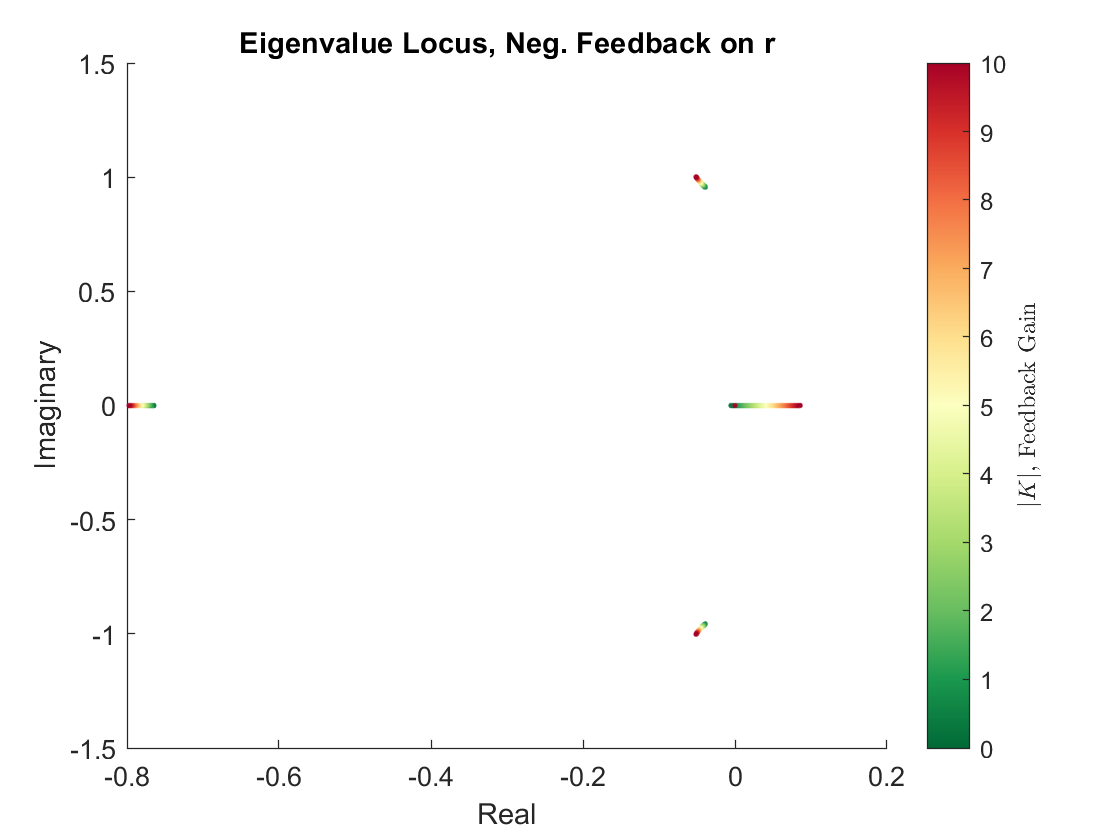

K = 0:0.01:10;
mycolormap = customcolormap(linspace(0,1,11), {'#a60126','#d7302a','#f36e43','#faac5d','#fedf8d','#fcffbf','#d7f08b','#a5d96b','#68bd60','#1a984e','#006936'}, length(K));
figure()
hold on
for i = 1:length(K)
    Klat(1, 1:6) = [0, 0, K(i), 0, 0, 0];
    Klat(2, 1:6) = [0, 0, 0,    0, 0, 0];
    ALatAugCL = Alat - Blat * Klat;
    [VCL, DCL] = eig(ALatAugCL);
    DCL = diag(DCL);
    plot(DCL, 'Color', mycolormap(i,:), 'Marker', '.', 'LineStyle', 'none');
end
colormap(mycolormap);
gaincol = colorbar();
caxis([0 10]);
gaincol.Label.String = '$\left| K \right|$, Feedback Gain';
gaincol.Label.Interpreter = 'latex';
title('Eigenvalue Locus, Neg. Feedback on r');
xlabel('Real');
ylabel('Imaginary');
hold off

K = 0;
Klat = 0;
ALatAugCL = 0;
VCL = 0;
DCL = 0;

Using r to control the feedback for aileron control primarily affects the Spiral mode.  Specifically, the Spiral mode is made unstable with this control.  Additionally, the Dutch Roll mode's frequency is shrunk and the damping ratio is increased, and the Roll mode's time constant is shrunk as well.

On the graph, the Dutch Roll mode is found at the top and bottom, while the Roll mode is found on the left hand side, and the Spiral mode is found on the right side of the center of the graph.

### d) $\Delta \delta_a = K \Delta \psi$, $\Delta \delta_r = 0$, $\left| K \right| = 0 \colon 0.01 \colon 20$ (pos. feedback only)

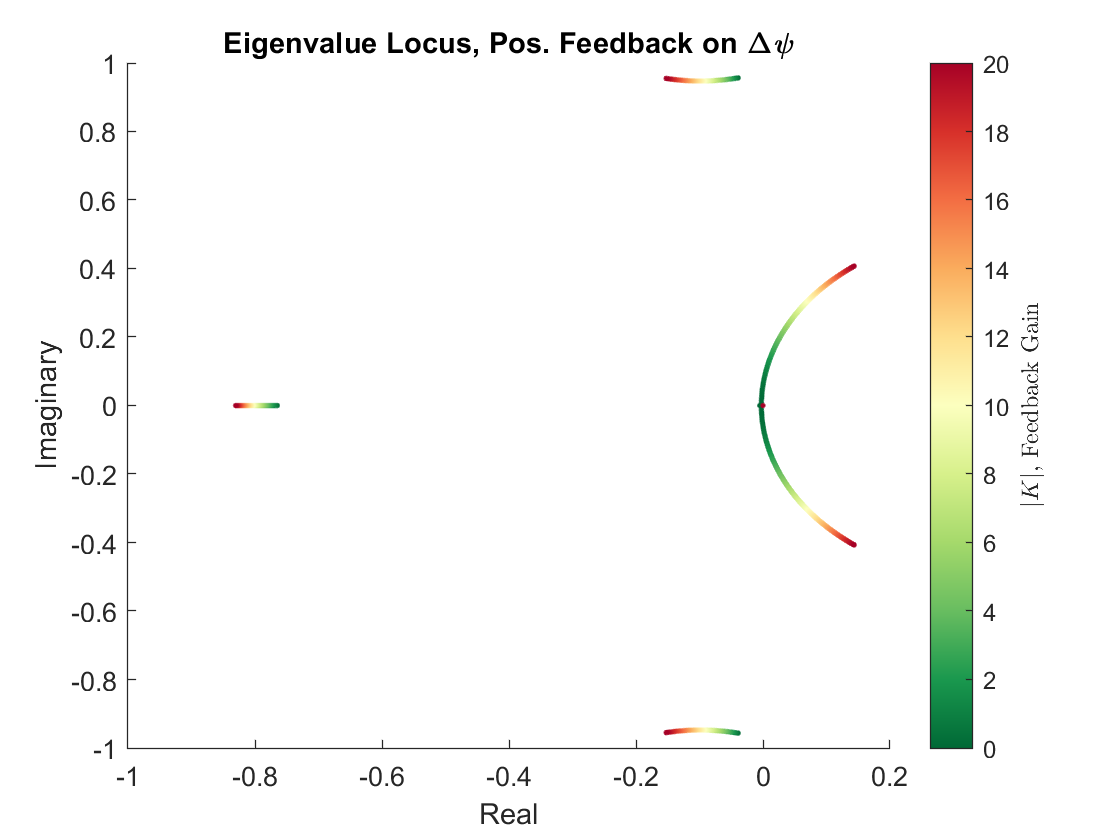

K = 0:0.01:20;
mycolormap = customcolormap(linspace(0,1,11), {'#a60126','#d7302a','#f36e43','#faac5d','#fedf8d','#fcffbf','#d7f08b','#a5d96b','#68bd60','#1a984e','#006936'}, length(K));
figure()
hold on
for i = 1:length(K)
    Klat(1, 1:6) = [0, 0, 0, 0, K(i), 0];
    Klat(2, 1:6) = [0, 0, 0, 0,    0, 0];
    ALatAugCL = Alat + Blat * Klat;
    [VCL, DCL] = eig(ALatAugCL);
    DCL = diag(DCL);
    plot(DCL, 'Color', mycolormap(i,:), 'Marker', '.', 'LineStyle', 'none');
end
%plot(DCL, '.r')
colormap(mycolormap);
gaincol = colorbar();
caxis([0 20]);
gaincol.Label.String = '$\left| K \right|$, Feedback Gain';
gaincol.Label.Interpreter = 'latex';
title('Eigenvalue Locus, Pos. Feedback on \Delta\psi');
xlabel('Real');
ylabel('Imaginary');
hold off

K = 0;
Klat = 0;
ALatAugCL = 0;
VCL = 0;
DCL = 0;

Using feedback from $\psi$ on the aileron control, we observe the primary mode that is affected is the Spiral mode.  The initial nonperiodic mode combines with the zero root to form an oscillatory mode.  At very small gains, (i.e. $\left| K \right| \approx 0.5$), the mode becomes unstable.  Additionally, the Dutch Roll becomes more heavily damped.  Finally, the Roll mode time constant becomes smaller.  

On the graph, the Dutch Roll mode can be found at the top and bottom of the graph, with the Roll mode on the far left, and the Spiral mode on the right side, illustrated by the semi-circle.

### e) $\Delta \delta_a = 0$, $\Delta \delta_r = K\Delta v$, $\left| K \right| = 0 \colon 0.0001 \colon 0.1$ (neg. feedback only)

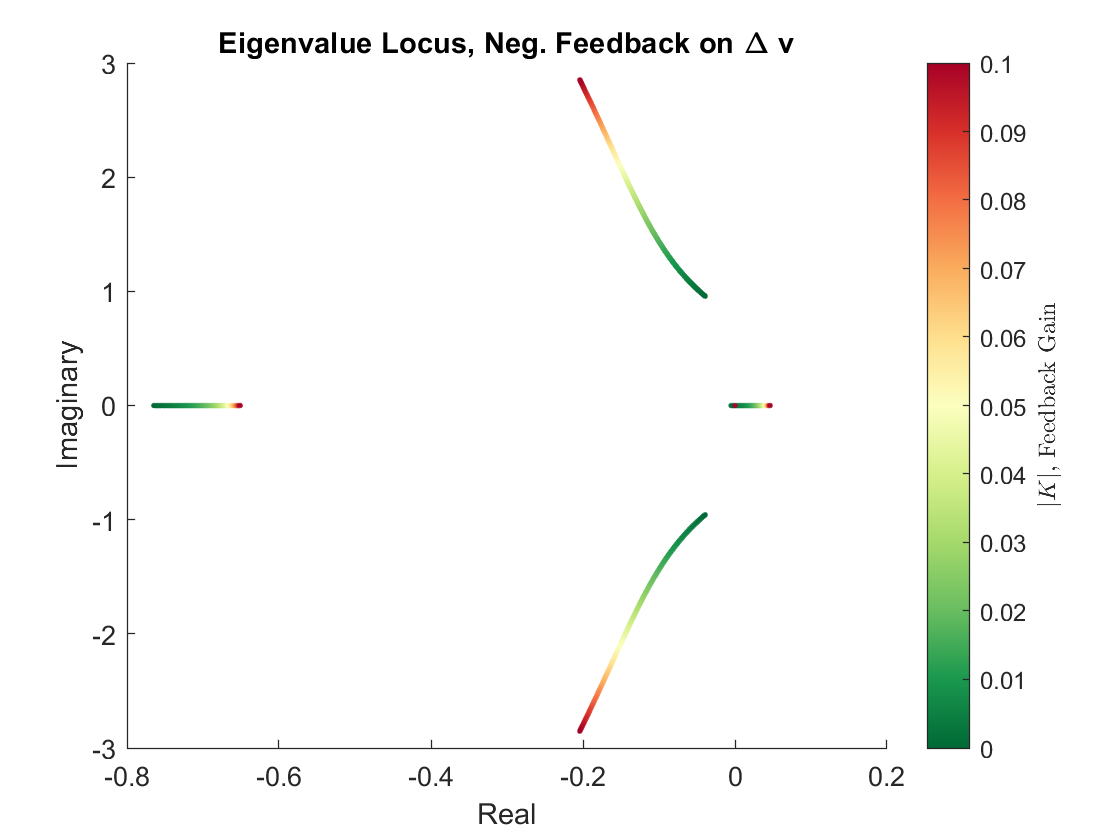

K = 0:0.0001:0.1;
mycolormap = customcolormap(linspace(0,1,11), {'#a60126','#d7302a','#f36e43','#faac5d','#fedf8d','#fcffbf','#d7f08b','#a5d96b','#68bd60','#1a984e','#006936'}, length(K));
figure()
hold on
for i = 1:length(K)
    Klat(1, 1:6) = [0,    0, 0, 0, 0, 0];
    Klat(2, 1:6) = [K(i), 0, 0, 0, 0, 0];
    ALatAugCL = Alat - Blat * Klat;
    [VCL, DCL] = eig(ALatAugCL);
    DCL = diag(DCL);
    plot(real(DCL), imag(DCL), 'Color', mycolormap(i,:), 'Marker', '.', 'LineStyle', 'none');
end
colormap(mycolormap);
gaincol = colorbar();
caxis([0 0.1]);
gaincol.Label.String = '$\left| K \right|$, Feedback Gain';
gaincol.Label.Interpreter = 'latex';
title('Eigenvalue Locus, Neg. Feedback on \Delta v');
xlabel('Real');
ylabel('Imaginary');
hold off

K = 0;
Klat = 0;
ALatAugCL = 0;
VCL = 0;
DCL = 0;

This feedback represents rudder angle proportional to sideslip.  The primary effect of this feedback is to increase the Dutch Roll mode frequency while simultaneously decreasing the Spiral mode stability.  The Spiral mode goes unstable as $\left| K \right|$ is increased.  The Roll mode is largely unaffected.

### f) $\Delta \delta_a = 0$, $\Delta \delta_r = K\Delta p$, $\left| K \right| = 0 \colon 0.01 \colon 2$ (neg. feedback only)

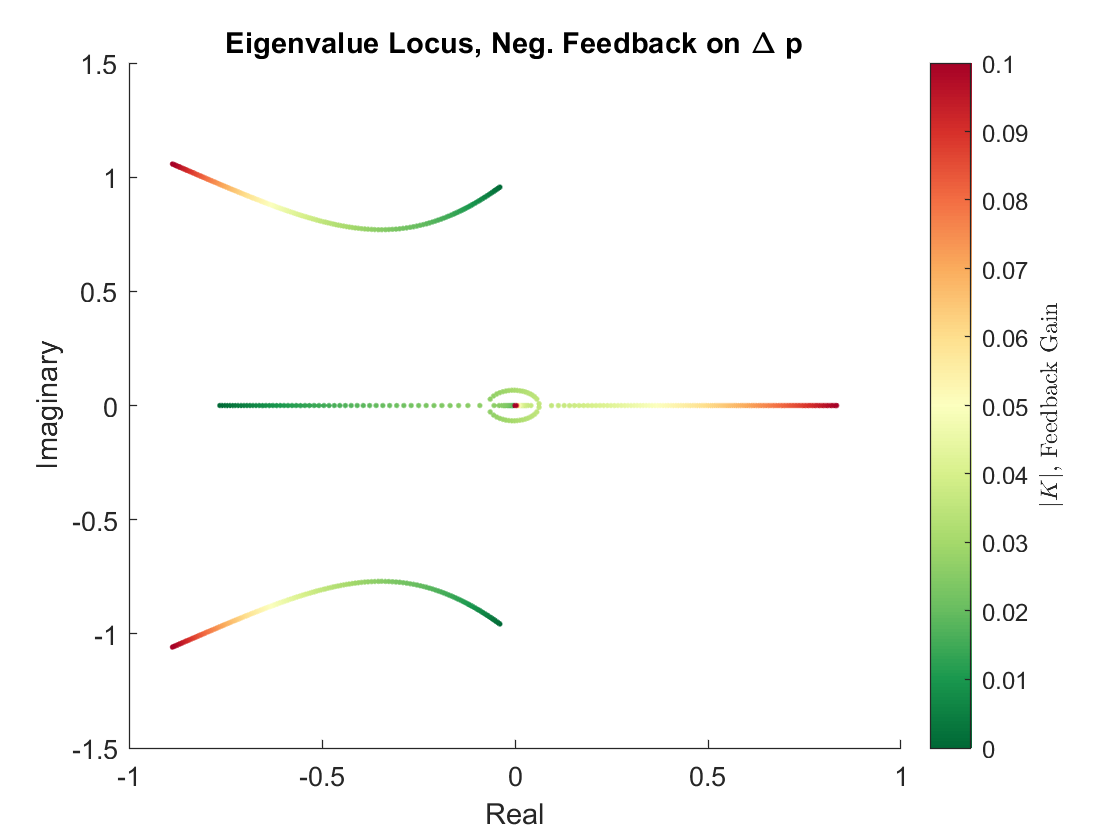

K = 0:0.01:2;
mycolormap = customcolormap(linspace(0,1,11), {'#a60126','#d7302a','#f36e43','#faac5d','#fedf8d','#fcffbf','#d7f08b','#a5d96b','#68bd60','#1a984e','#006936'}, length(K));
figure()
hold on
for i = 1:length(K)
    Klat(1, 1:6) = [0, 0,    0, 0, 0, 0];
    Klat(2, 1:6) = [0, K(i), 0, 0, 0, 0];
    ALatAugCL = Alat - Blat * Klat;
    [VCL, DCL] = eig(ALatAugCL);
    DCL = diag(DCL);
    plot(real(DCL), imag(DCL), 'Color', mycolormap(i,:), 'Marker', '.', 'LineStyle', 'none');
end
colormap(mycolormap);
gaincol = colorbar();
caxis([0 0.1]);
gaincol.Label.String = '$\left| K \right|$, Feedback Gain';
gaincol.Label.Interpreter = 'latex';
title('Eigenvalue Locus, Neg. Feedback on \Delta p');
xlabel('Real');
ylabel('Imaginary');
hold off

K = 0;
Klat = 0;
ALatAugCL = 0;
VCL = 0;
DCL = 0;

Feeding the Roll rate back to the rudder has a large effect on all three modes.  As the gain is increased, the Dutch Roll mode damping ratio is increased very dramatically.  At the same time, the damping ratio of the Roll mode is diminished significantly, and the damping ratio for the Spiral mode is increased.  Above a gain of $\left| K \right| \approx 0.3$, the two nonperiodic modes combine to form an oscillation, which is unstable above $\left| K \right| \approx 0.4$.  The oscillation splits into the two nonperiodic modes again, and the Spiral mode becomes more stable, while the Roll mode's unstability is drastically increased.

The Dutch Roll is found at the top and bottom (primarily left of center), while the Roll and Spiral modes are found along the '0' line.

### g) $\Delta \delta_a = 0$, $\Delta \delta_r = K\Delta r$, $\left| K \right| = 0 \colon 0.01 \colon 5$ (neg. & pos. feedback)

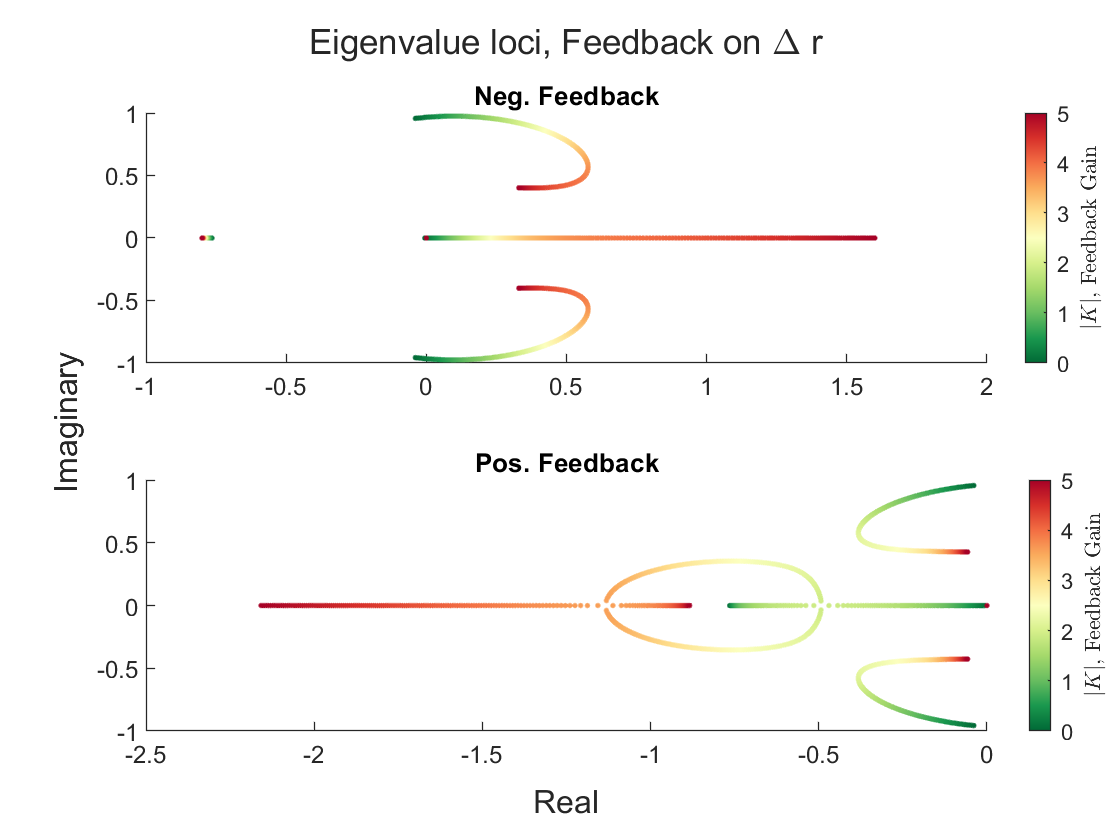

K = 0:0.01:5;
mycolormap = customcolormap(linspace(0,1,11), {'#a60126','#d7302a','#f36e43','#faac5d','#fedf8d','#fcffbf','#d7f08b','#a5d96b','#68bd60','#1a984e','#006936'}, length(K));
figure()
tiles = tiledlayout(2, 1);
ti = title(tiles, ['Eigenvalue loci, Feedback on \Delta r']);
nexttile
hold on
for i = 1:length(K)
    Klat(1, 1:6) = [0, 0, 0, 0, 0, 0];
    Klat(2, 1:6) = [0, 0, K(i), 0, 0, 0];
    ALatAugCL = Alat - Blat * Klat;
    [VCL, DCL] = eig(ALatAugCL);
    DCL = diag(DCL);
    plot(real(DCL), imag(DCL), 'Color', mycolormap(i,:), 'Marker', '.', 'LineStyle', 'none');
end
colormap(mycolormap);
gaincol = colorbar();
caxis([0 5]);
gaincol.Label.String = '$\left| K \right|$, Feedback Gain';
gaincol.Label.Interpreter = 'latex';
title('Neg. Feedback');
hold off

nexttile
hold on
for i = 1:length(K)
    Klat(1, 1:6) = [0, 0, 0, 0, 0, 0];
    Klat(2, 1:6) = [0, 0, K(i), 0, 0, 0];
    ALatAugCL = Alat + Blat * Klat;
    [VCL, DCL] = eig(ALatAugCL);
    DCL = diag(DCL);
    plot(real(DCL), imag(DCL), 'Color', mycolormap(i,:), 'Marker', '.', 'LineStyle', 'none');
end
colormap(mycolormap);
gaincol = colorbar();
caxis([0 5]);
gaincol.Label.String = '$\left| K \right|$, Feedback Gain';
gaincol.Label.Interpreter = 'latex';
title('Pos. Feedback')
xlabel(tiles, 'Real');
ylabel(tiles, 'Imaginary');
hold off

K = 0;
Klat = 0;
ALatAugCL = 0;
VCL = 0;
DCL = 0;

For the negative feedback case, primarily the Spiral and Dutch Roll modes are affected.  The Dutch Roll mode rapidly becomes unstable, and the Spiral mode does the same.  Interestingly, no additional oscillations are created.

For the positve feedback case, all three modes are affected by this control.  The Dutch Roll mode becomes more damped up to a point, and then the damping ratio is reduced to almost 0.  The Spiral mode becomes more stable, while the Roll mode becomes less stable.  Eventually, the two nonperiodic modes comine to form an oscillation, until splitting apart again.  The Spiral mode continues to become more stable with a smaller time constant, while the Roll mode tends back towards its original value. 

### h) $\Delta \delta_a = 0$, $\Delta \delta_r = K\Delta \phi$, $\left| K \right| = 0 \colon 0.01 \colon 5$ (neg. & pos. feedback)

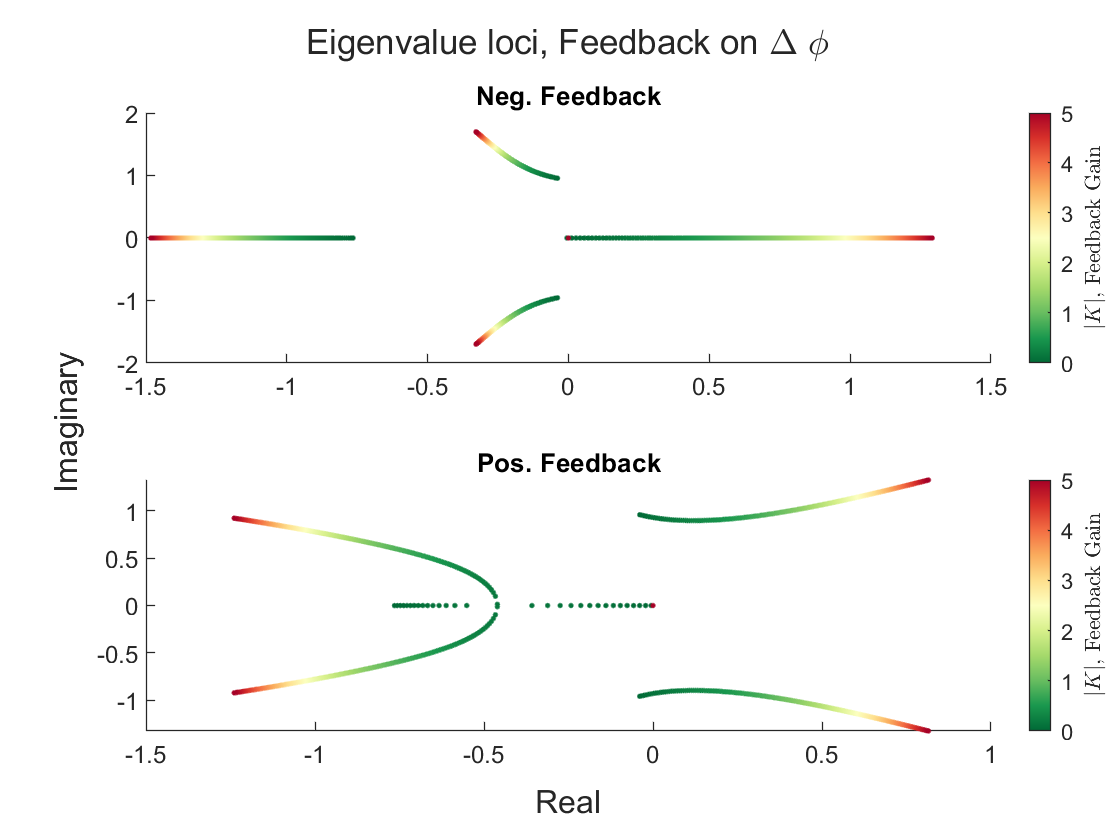

K = 0:0.01:5;
mycolormap = customcolormap(linspace(0,1,11), {'#a60126','#d7302a','#f36e43','#faac5d','#fedf8d','#fcffbf','#d7f08b','#a5d96b','#68bd60','#1a984e','#006936'}, length(K));
figure()
tiles = tiledlayout(2, 1);
ti = title(tiles, ['Eigenvalue loci, Feedback on \Delta \phi']);
nexttile
hold on
for i = 1:length(K)
    Klat(1, 1:6) = [0, 0, 0, 0,    0, 0];
    Klat(2, 1:6) = [0, 0, 0, K(i), 0, 0];
    ALatAugCL = Alat - Blat * Klat;
    [VCL, DCL] = eig(ALatAugCL);
    DCL = diag(DCL);
    plot(real(DCL), imag(DCL), 'Color', mycolormap(i,:), 'Marker', '.', 'LineStyle', 'none');
end
colormap(mycolormap);
gaincol = colorbar();
caxis([0 5]);
gaincol.Label.String = '$\left| K \right|$, Feedback Gain';
gaincol.Label.Interpreter = 'latex';
title('Neg. Feedback');
hold off

nexttile
hold on
for i = 1:length(K)
    Klat(1, 1:6) = [0, 0, 0, 0,    0, 0];
    Klat(2, 1:6) = [0, 0, 0, K(i), 0, 0];
    ALatAugCL = Alat + Blat * Klat;
    [VCL, DCL] = eig(ALatAugCL);
    DCL = diag(DCL);
    plot(real(DCL), imag(DCL), 'Color', mycolormap(i,:), 'Marker', '.', 'LineStyle', 'none');
end
colormap(mycolormap);
gaincol = colorbar();
caxis([0 5]);
gaincol.Label.String = '$\left| K \right|$, Feedback Gain';
gaincol.Label.Interpreter = 'latex';
title('Pos. Feedback')
xlabel(tiles, 'Real');
ylabel(tiles, 'Imaginary');
hold off

K = 0;
Klat = 0;
ALatAugCL = 0;
VCL = 0;
DCL = 0;

For the negative feedback case, the Spiral mode is made unstable, while the Roll mode is made more stable.  However, the frequency of the Dutch Roll mode is increased as $\left| K \right|$ increases.

For the positive feedback case, the opposite occurs.  The Dutch roll is made unstable, while the two nonperiodic modes combine to form an oscillation.

### h) $\Delta \delta_a = 0$, $\Delta \delta_r = K\Delta \psi$, $\left| K \right| = 0 \colon 0.01 \colon 5$ (neg. & pos. feedback)

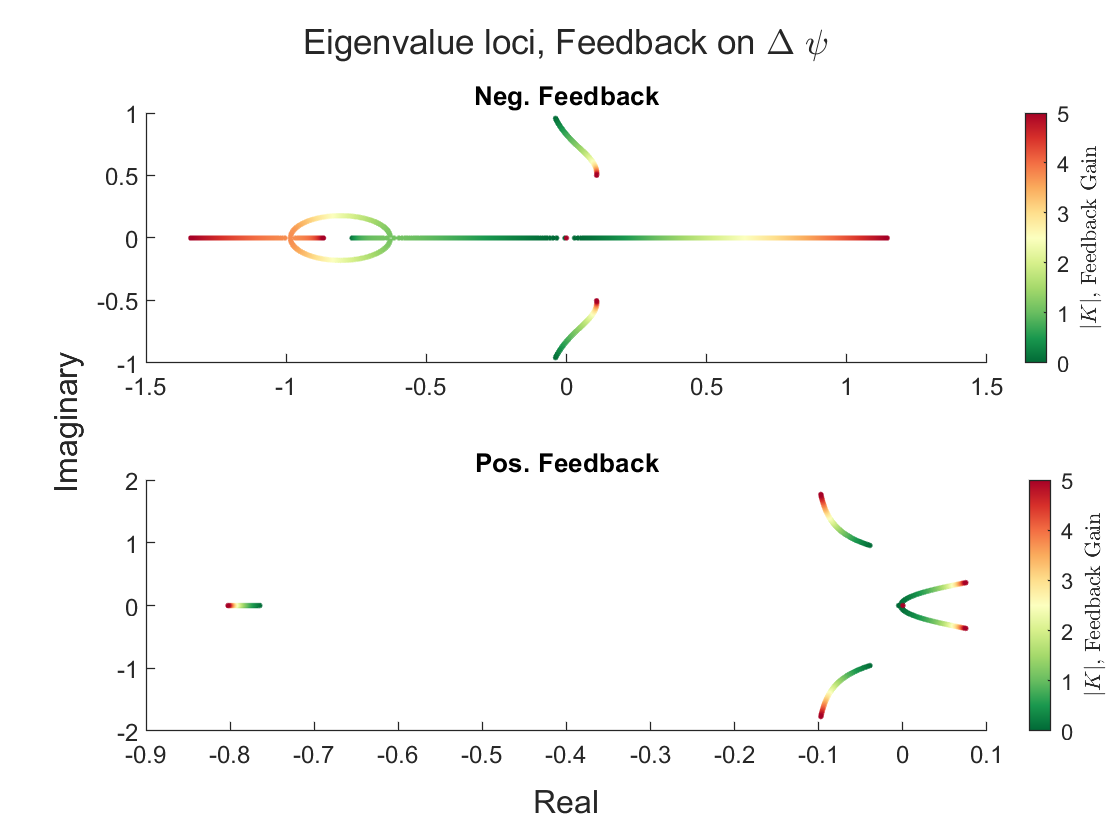

K = 0:0.01:5;
mycolormap = customcolormap(linspace(0,1,11), {'#a60126','#d7302a','#f36e43','#faac5d','#fedf8d','#fcffbf','#d7f08b','#a5d96b','#68bd60','#1a984e','#006936'}, length(K));
figure()
tiles = tiledlayout(2, 1);
ti = title(tiles, ['Eigenvalue loci, Feedback on \Delta \psi']);
nexttile
hold on
for i = 1:length(K)
    Klat(1, 1:6) = [0, 0, 0, 0, 0,    0];
    Klat(2, 1:6) = [0, 0, 0, 0, K(i), 0];
    ALatAugCL = Alat - Blat * Klat;
    [VCL, DCL] = eig(ALatAugCL);
    DCL = diag(DCL);
    plot(real(DCL), imag(DCL), 'Color', mycolormap(i,:), 'Marker', '.', 'LineStyle', 'none');
end
colormap(mycolormap);
gaincol = colorbar();
caxis([0 5]);
gaincol.Label.String = '$\left| K \right|$, Feedback Gain';
gaincol.Label.Interpreter = 'latex';
title('Neg. Feedback');
hold off

nexttile
hold on
for i = 1:length(K)
    Klat(1, 1:6) = [0, 0, 0, 0, 0,    0];
    Klat(2, 1:6) = [0, 0, 0, 0, K(i), 0];
    ALatAugCL = Alat + Blat * Klat;
    [VCL, DCL] = eig(ALatAugCL);
    DCL = diag(DCL);
    plot(real(DCL), imag(DCL), 'Color', mycolormap(i,:), 'Marker', '.', 'LineStyle', 'none');
end
colormap(mycolormap);
gaincol = colorbar();
caxis([0 5]);
gaincol.Label.String = '$\left| K \right|$, Feedback Gain';
gaincol.Label.Interpreter = 'latex';
title('Pos. Feedback')
xlabel(tiles, 'Real');
ylabel(tiles, 'Imaginary');
hold off

K = 0;
Klat = 0;
ALatAugCL = 0;
VCL = 0;
DCL = 0;

For negative heading feedback on rudder, the Dutch Roll mode is made unstable, and the frequency is reduced.  The null mode quickly becomes divergent, and the Roll mode and Spiral mode are made more stable.  

For positive heading feedback on rudder, the Dutch Roll has decreased damping ratio, and the Roll mode is largely unaffected.  The Spiral mode becomes divergent,